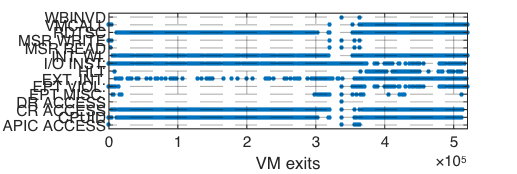

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Exit_N", "Exit_Name"];
opts.VariableTypes = ["double", "categorical"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Exit_Name", "EmptyFieldRule", "auto");

% Import the data
bootexitsovertime = readtable("boot_exits_over_time.csv", opts);

plot((1:size(bootexitsovertime.Exit_N)),bootexitsovertime.Exit_Name,'.');
ax=gca;

xlim([0 520000])

xlabel("VM exits");

ax = gca; 
ax.FontSize = 7;
%legend({'recording','replaying'},'Orientation',"horizontal","Location","south")
grid on
ax = gca;
ax.GridColor = [0 0 0];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.3;
ax.Layer = 'top';



set(gcf,'units','points','position',[10,10,625,210])